# Mockup of Intro to proposed ciCamera Class

ciCamera is one of a set of classes that allow experimentation with computational imaging more directly than the previous "lower-level" scene, oi, sensor, and ip structs. Along with ciScene and ciCModule they provide a programmable wrapper that allows users to create "cameras" that have a variety of algorithms for deciding how to capture a scene, and then how to process one or more captures, potentially even from more than one camera module (ciCModule).

History: Initial Version: D. Cardinal 12/2020

ieInit();
ourCamera = ciBurstCamera(); % probably will pass init args
ourCamera.cmodule = ciCModule(); % default

Now we'll define our scene

scenePath = 'Cornell_BoxBunnyChart';        
sceneName = 'cornell box bunny chart';
ourScene = ciScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName);

Read 11 materials
Read 3 textures
Reading C4D geometry information.


optionally set camera and object motion here through parameters/methods of ourScene. 

This sets the Stanford bunny in motion with a vertical movement of about 5cm/s (?) and a tiny rotation.

ourScene.objectMotion = {{'Default_B', [0, 5, 0], [1, 1, 1]}};

For the simplest case we ask our camera to take a picture. By deault it uses the 'Auto' intent. Using 'Burst' will capture more frames if the camera type we are using supports it:

Read 11 materials
Read 3 textures
Reading C4D geometry information.
New light added.
Reading multispectral data with raw data.
Read 11 materials
Read 3 textures
Reading C4D geometry information.
New light added.
Reading multispectral data with raw data.
Reading multispectral data with raw data.
Reading multispectral data with raw data.


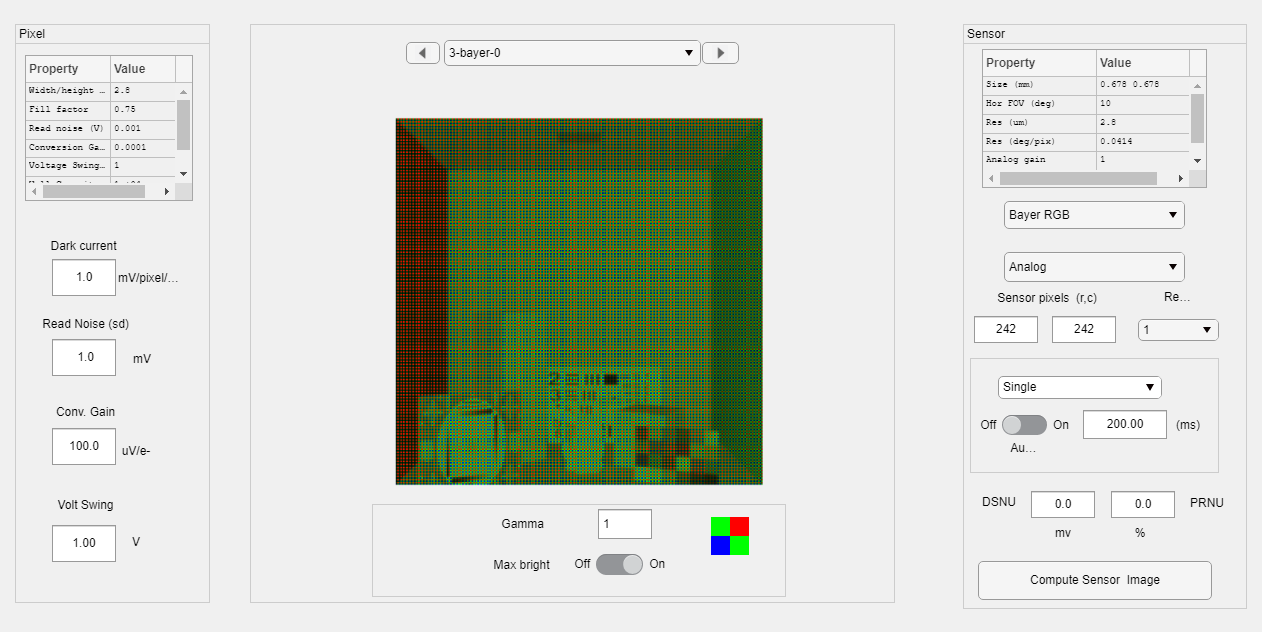

finalImage = ourCamera.TakePicture(ourScene, 'HDR');

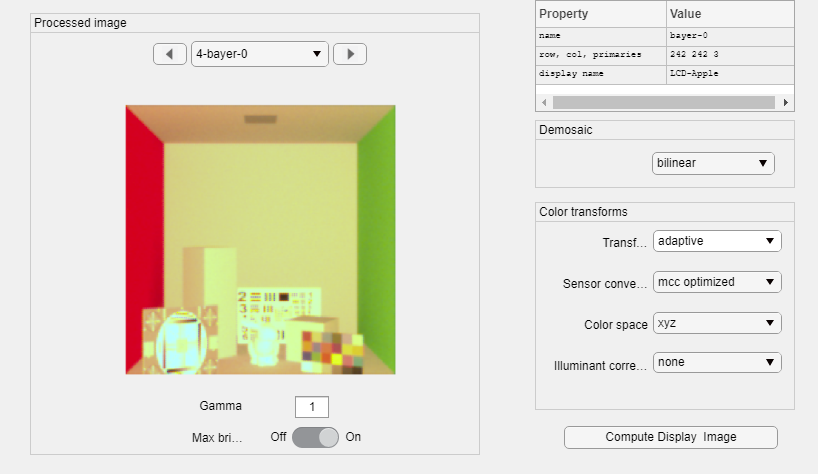

%finalImage = ourCamera.TakePicture(ourScene, 'Burst');
ipWindow(finalImage); % let's see what we got